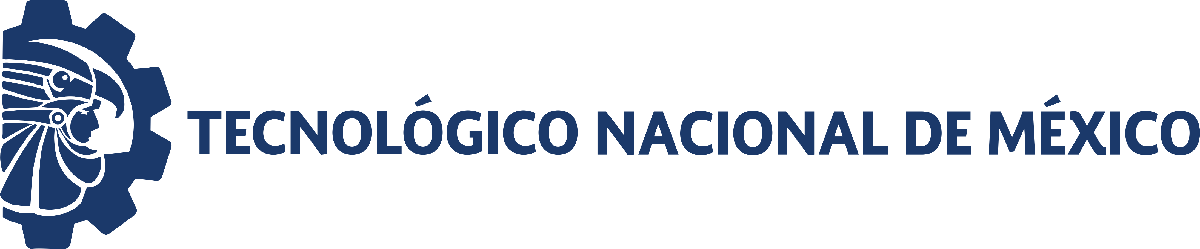                                 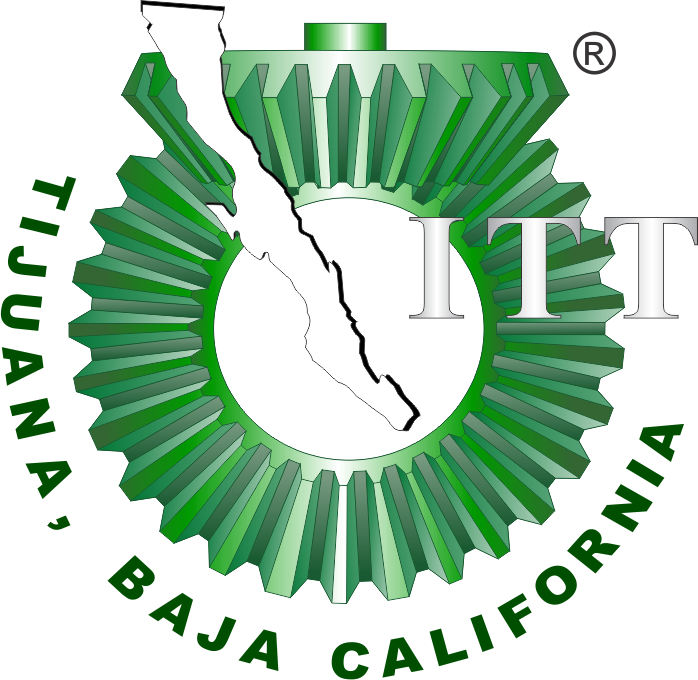

# Práctica 4: Modelizado matemático

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

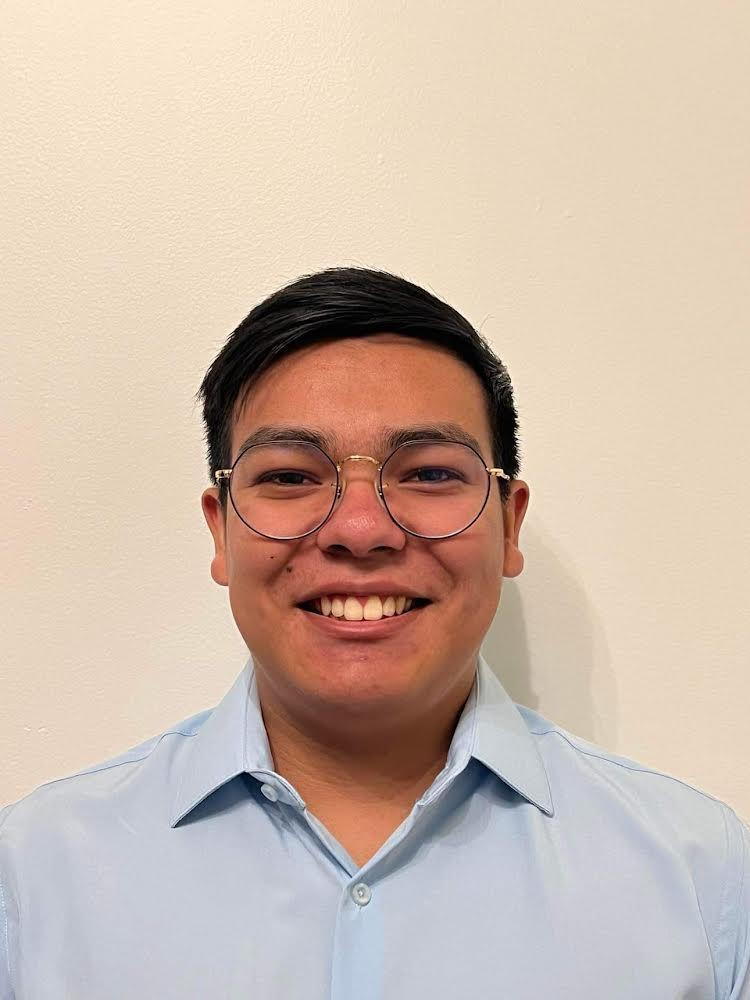

Nombre del alumno: **Alexander Torres Avila**

Número de control: **21212848**

Correo institucional: **L21212848@tectijuana.edu.mx**

Carrera: **Ing. Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1); x1o = sys(:,2); y1o = sys(:,3);
T = array2table([to,x1o,y1o],'VariableNames',{'t [days]','xo','yo'}); disp(T)

    t [days]      xo         yo   
    ________    _______    _______

        0       0.83086    0.99501
        5         1.662     2.5145
       10        2.2956     4.8358
       15         2.837     6.9758
       20        3.9255     6.9853
       25        3.9262     7.2348
       30        4.7409     6.7614
       35        4.5751     6.3823
       40        5.2588     6.3545
       45        5.1664     6.1724
       50        5.8318     6.0549
       55         6.006     4.8586
       60        5.8311     5.5353
       65        5.8493      5.113
       70        6.5819     5.3388
       75        6.8798     4.7416
       80        6.3799     4.5736
       85        6.8302     4.7893
       90        6.6908     4.1221
       95        7.1671     4.3096
      100        7.1736     4.6394
      105        6.6341      4.249
      110        7.3832      4.463
      115        7.558

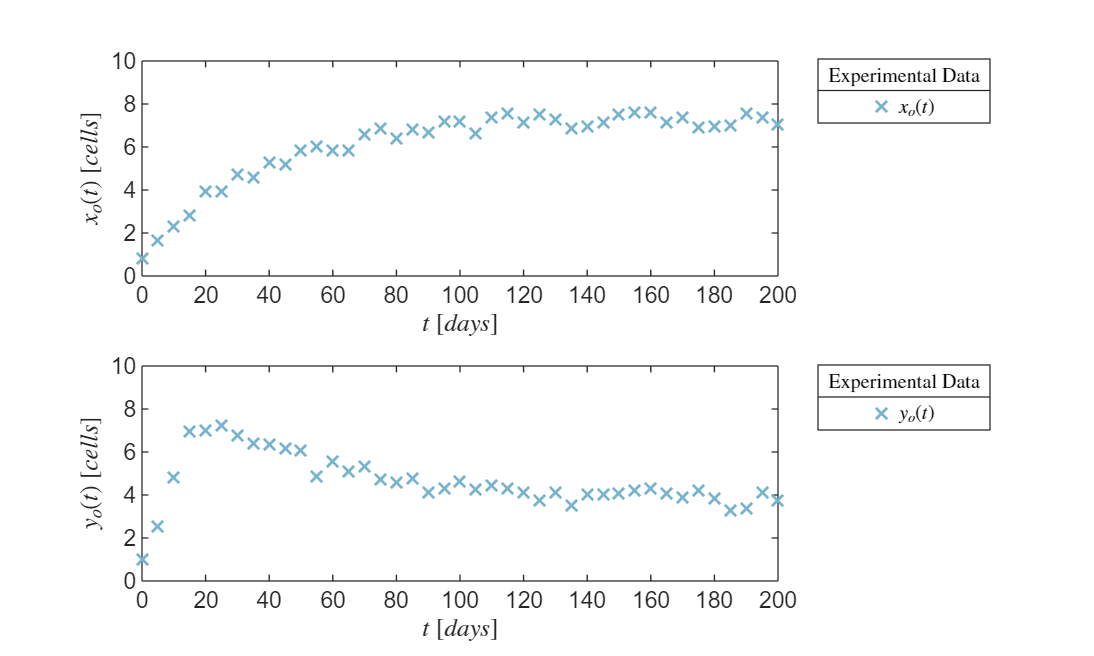

plotData(to,x1o,y1o); ttl = ''; sgtitle(ttl,'Interpreter','Latex')
exportgraphics(gcf, 'data.pdf','ContentType','vector')

### Nonlinear regression algorithm


$$\dot{x} =\rho_1 x\left(1-\frac{x+\gamma_1 y}{\beta }\right)$$



$$\dot{y} =\rho_2 y\left(1-\frac{y+\gamma_2 x}{\beta }\right)$$



$$\beta =10$$


rho1 = max(x1o); rho2 = max(y1o); gamma1 = 0.5; gamma2 = 0.5;
P = [rho1,gamma1,rho2,gamma2];
P0 = [0.1;0.1;0.1;0.1];
[mdl,xa,ya] = variant(to,x1o,y1o,P0); plotresults(to,[x1o,xa],[y1o,ya]); 


Sample size (n): 41
Parameters to be estimated (pars): 4
Degrees of freedom: 78
Significance level (alpha): 0.05
t-Student values: 1.9908
Adjusted R-squared: 0.97322
Corrected AIC (n/pars < 40): 25.358

    Parameters    Estimate       SE          MoE              CI95             Pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053859    0.010723    0.14193    0.16337    8.0593e-43
      gamma1      0.27412      0.011137    0.022173    0.25195     0.2963    1.6195e-38
      rho2        0.67149      0.012893    0.025668    0.64582    0.69716    2.3483e-62
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9951e-84



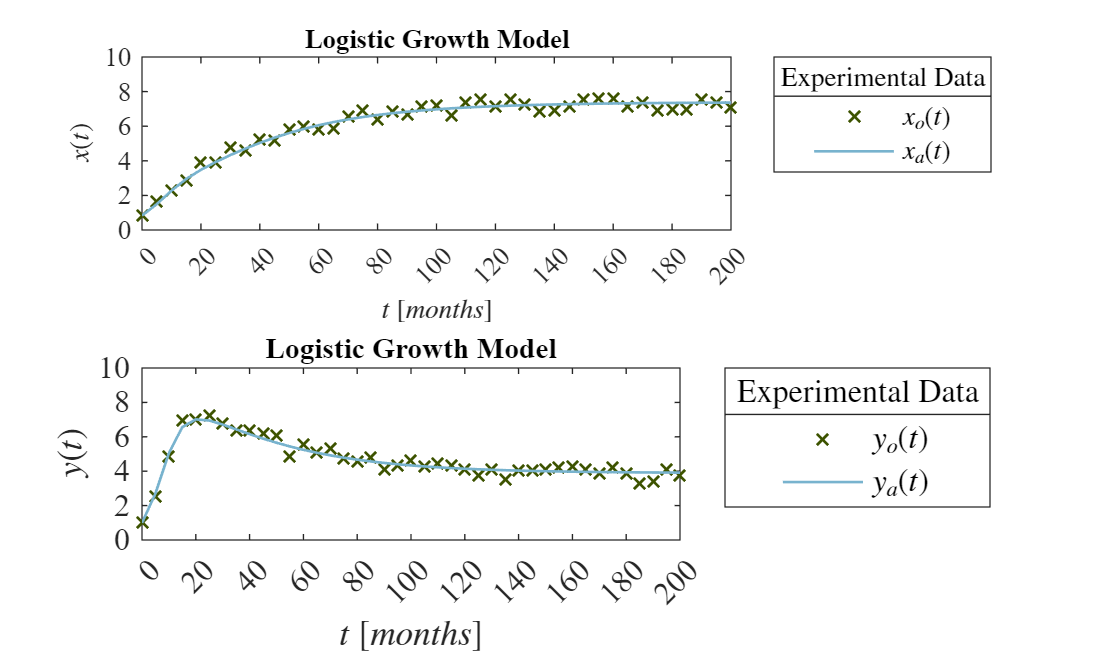

exportgraphics(gcf, 'x1a.pdf','ContentType','vector')

## Equilibrium points and Jacobian matrix

clear; close all; clc
syms x y rho1 rho2 gamma1 gamma2 beta
dx = rho1*x *((1-(x+gamma1*y)/beta));
dy = rho2*y *((1-(y+gamma2*x)/beta));
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the system:'); disp(J)

Jacobian matrix of the system:

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$

dx = rho1*x *((1-(x+gamma1*y)/beta))==0;
dy = rho2*y *((1-(y+gamma2*x)/beta))==0;
edos = solve([dx,dy],[x,y]);
fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.'])

The system has 4 equilibrium points.

X0 = edos.x(1); Y0= edos.y(1);
X1 = edos.x(2); Y1= edos.y(2);
X2 = edos.x(3); Y2= edos.y(3);
X3 = edos.x(4); Y3= edos.y(4);
syms x0 y0 x1 y1 x2 y2 x3 y3
fprintf('Equilibrium points of the system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3]);

Equilibrium points of the system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$

clear gamma1 gamma2 beta
gamma1 = 0.67149;     gamma2 = 0.82706;
beta = 10;
disp('(x0,y0) = (0,0)'); 

(x0,y0) = (0,0)


disp(['(x1,y1) = (', num2str(beta), ',0)']);

(x1,y1) = (10,0)


disp(['(x2,y2) = (0,', num2str(beta), ')']);

(x2,y2) = (0,10)


disp(['(x3,y3) = (', num2str((beta*(gamma1-1)/(gamma1*gamma2-1))), ',', num2str((beta*(gamma2-1)/(gamma1*gamma2-1))), ')'])

(x3,y3) = (7.3883,3.8895)


## Local estability

clc; clear;
rho1 = 0.15265;       rho2 = 0.27411; 
gamma1 = 0.67149;     gamma2 = 0.82706;
beta = 10;
syms x y
dx = rho1*x *((1-(x+gamma1*y)/beta)) ==0;
dy = rho2*y *((1-(y+gamma2*x)/beta))==0;
edos = solve([dx,dy],[x,y]);
x0 = double(edos.x(1)); y0= double(edos.y(1));
x1 = double(edos.x(2)); y1= double(edos.y(2));
x2 = double(edos.x(3)); y2= double(edos.y(3));
x3 = double(edos.x(4)); y3= double(edos.y(4));
clear x y 
x = [x0; x1; x2; x3]; y = [y0; y1;y2;y3];
var = {'(x0,y0)'; '(x1,y1)';'(x2,y2)';'(x3,y3)'};
Equilibria = table(x,y, 'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the system:\n'); disp(Equilibria)

Equilibrium points of the system:
                 xe        ye  
               ______    ______

    (x0,y0)         0         0
    (x1,y1)        10         0
    (x2,y2)         0        10
    (x3,y3)    7.3883    3.8895



L = zeros(length(x), 2); 

for i = 1:length(x)
    J = [ -rho1*((x(i)+gamma1*y(i))/beta - 1) - (rho1*x(i))/beta,        - (gamma1*rho1*x(i))/beta;
          - (gamma2*rho2*y(i))/beta,                                     -rho2*((y(i)+gamma2*x(i))/beta - 1) - (rho2*y(i))/beta ];
    
    fprintf('\nJacobian matrix at (x%d, y%d):\n', i-1, i-1);
    disp(J)
    
    L(i,:) = eig(J).';
end


Jacobian matrix at (x0, y0):


    0.1527         0
         0    0.2741




Jacobian matrix at (x1, y1):


   -0.1527   -0.1025
         0    0.0474




Jacobian matrix at (x2, y2):


    0.0501         0
   -0.2267   -0.2741




Jacobian matrix at (x3, y3):


   -0.1128   -0.0757
   -0.0882   -0.1066



L1 = L(:,1); 
L2 = L(:,2);
Lambdas = table(L1, L2, 'RowNames', var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:');disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1          L2    
               ________    _________

    (x0,y0)     0.15265      0.27411
    (x1,y1)    -0.15265     0.047405
    (x2,y2)    -0.27411     0.050147
    (x3,y3)    -0.19147    -0.027922



***(x0,y0)*** no presenta ninguna estabilidad, tampoco inestabilidad debido a que la parte de los valores propios uno es negativo y uno es positivo, presentando una igualdad de los valores imaginarios en cero.

***(x1,y1)*** es inestable, debido a que es parte de los casos marginales, especificamente centros, ya que los valores propios son imaginarios y su parte real es igual a cero y solo aplicaría una estabilidad si se presentaría uno de los valores propios igual a cero.

## Equilibrium points

sys = readmatrix('data.csv');
to = sys(:,1); x1o = sys(:,2); y1o = sys(:,3);
P0 = [0.1;0.1;0.1;0.1];
[mdl,xa,ya] = variant(to,x1o,y1o,P0); plotEqui(to,[x1o,xa],[y1o,ya]); 


Sample size (n): 41
Parameters to be estimated (pars): 4
Degrees of freedom: 78
Significance level (alpha): 0.05
t-Student values: 1.9908
Adjusted R-squared: 0.97322
Corrected AIC (n/pars < 40): 25.358

    Parameters    Estimate       SE          MoE              CI95             Pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053859    0.010723    0.14193    0.16337    8.0593e-43
      gamma1      0.27412      0.011137    0.022173    0.25195     0.2963    1.6195e-38
      rho2        0.67149      0.012893    0.025668    0.64582    0.69716    2.3483e-62
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9951e-84



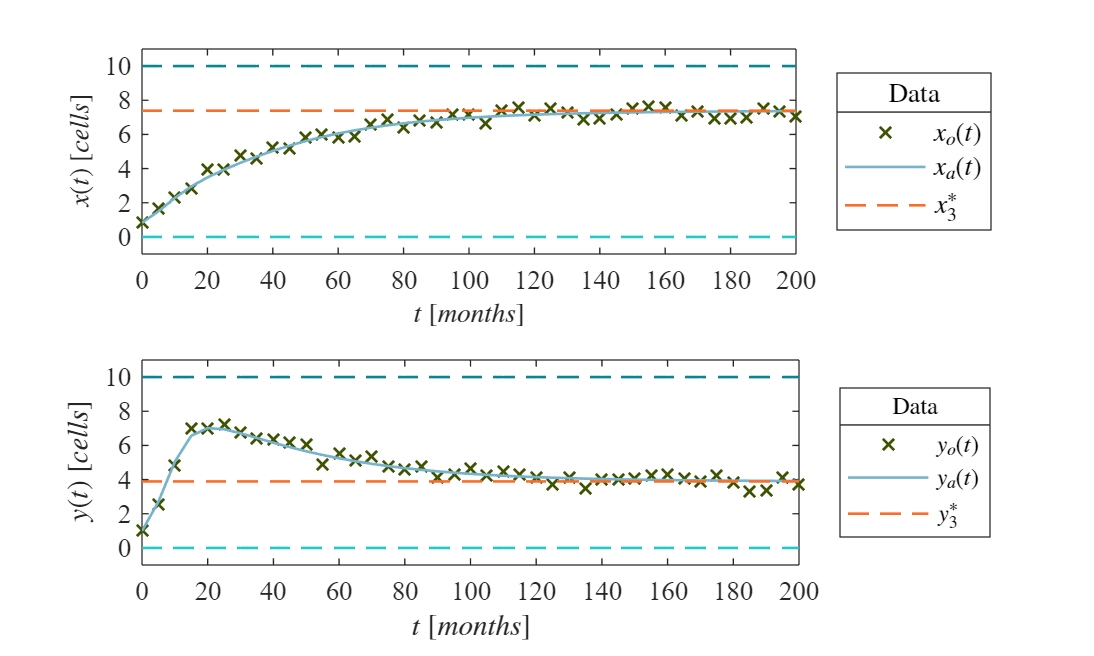

exportgraphics(gcf, 'Equillibrium.pdf','ContentType','vector')

## Functions

function plotData(t,x,y)
    set(figure(1),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    c1=[120, 179, 206]/255;  

    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    title('Experimental data')

    subplot(2,1,1)
    plot(t,x,'x','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend('$x_o(t)$');
    set(L,'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Experimental Data')
    ylim([0, 10]); yticks(0:2:10);
    xlim([0, 200]); xticks(0:20:200);

    subplot(2,1,2)
    plot(t,y,'x','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y_o(t)$ $[cells]$','Interpreter','latex')
    L = legend('$y_o(t)$');
    set(L,'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Experimental Data')
    ylim([0, 10]); yticks(0:2:10);
    xlim([0, 200]); xticks(0:20:200);
end

### Nonlinear regression algorithm: Logistic growth law

function [mdl,xa,ya] = variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(P,t)
        beta = 10; rho1= P(1); rho2= P(2); gamma1 = P(3); gamma2 = P(4);
        dt = 1E-1;
        t = reshape(t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        
        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);
    
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end
    
        function [dx,dy] = f(x,y)
            dx = rho1*x*(1 - (x+gamma1*y)/beta);
            dy = rho2*y*(1 - (y+gamma2*x)/beta);
        end

        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        
        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);
    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1); ya = fx(:,2);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student values: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    disp(Results)
end

### Plot fitted and observed data

function plotresults(t,x,y)
    set(figure(2),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    
    c1=[120, 179, 206]/255; 
    c3=[61, 83, 0]/255; 
    FS = 12;
    subplot(2,1,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','LineWidth',1,'Color',c3)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',FS,'Location','NorthEastOutside')
    title(L,'Experimental Data')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    title('Logistic Growth Model', 'FontSize', 11);
    ylim([0, 10]); yticks(0:2:10);
    xlim([0, 200]); xticks(0:20:200);
    
    subplot(2,1,2)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','LineWidth',1,'Color',c3)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','FontSize',FS,'Location','NorthEastOutside')
    title(L,'Experimental Data')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    title('Logistic Growth Model', 'FontSize', 11);
    ylim([0, 10]); yticks(0:2:10);
    xlim([0, 200]); xticks(0:20:200);
    
end

function plotEqui(t,x,y)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    
    c1=[120, 179, 206]/255;  
    c2=[249, 110, 42]/255;  
    c3=[61, 83, 0]/255; 
    c4=[37, 200, 200]/255;
    c5=[11, 132, 148]/255;;

    subplot(2,1,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x(:,1),'x','LineWidth',1,'Color',c3)
    plot(t,x(:,2),'-','LineWidth',1,'Color',c1)
    plot(t,repmat(7.3883,1,length(t)),'--','LineWidth',1,'Color',c2)
    plot(t,zeros(length(t)),'--','LineWidth',1,'Color',c4)
    plot(t,repmat(10,1,length(t)),'--','LineWidth',1,'Color',c5)

    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x(t)$ $[cells]$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$','$x^*_3$','','');
    set(L,'Interpreter','latex','Location','eastoutside','Box','on')
    L.Title.String = 'Data';
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)

    subplot(2,1,2)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y(:,1),'x','LineWidth',1,'Color',c3)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c1)
    plot(t,repmat(3.8895,1,length(t)),'--','LineWidth',1,'Color',c2)
    plot(t,zeros(length(t)),'--','LineWidth',1,'Color',c4)
    plot(t,repmat(10,1,length(t)),'--','LineWidth',1,'Color',c5)

    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$y(t)$ $[cells]$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$','$y^*_3$','','');
    set(L,'Interpreter','latex','Location','eastoutside','Box','on')
    L.Title.String = 'Data';
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)
end